#                                      SPEECH PROCESSING LAB

#                                                    LAB-9

## `Aim:`

- To compute LP coefficients and LP residual of a given speech signal.

- To compute the formant parameters by LP analysis.

- To compute the excitation parameters like pitch by LP analysis.

- To compute the normalized error curves for voiced and unvoiced segments of speech.

**Codes and Plots:**

A)Estimating Linear Prediction (LP) coefficients from the speech.

Select a frame (25 ms long) at the center of a voiced segment. Estimate the LPCs of the segment using the autocorrelation method.

%Lab9
%linear prediction analysis-time domain 
%A)Estimating Linear Prediction (LP) coefficients from the speech.
%a)Select a frame (25 ms long) at the center of a voiced segment. Estimate the LPCs of the segment using the autocorrelation method.
[y,fs]=audioread('speech_signal.wav')

y =    -0.1831   -0.1831
   -0.2747   -0.2747
   -0.1221   -0.1221
   -0.4883   -0.4883
   -0.2747   -0.3052
   -0.1831   -0.1831
   -0.2136   -0.2136
    0.0610    0.0610
   -0.0610   -0.0610
   -0.1526   -0.1831


fs = 16000

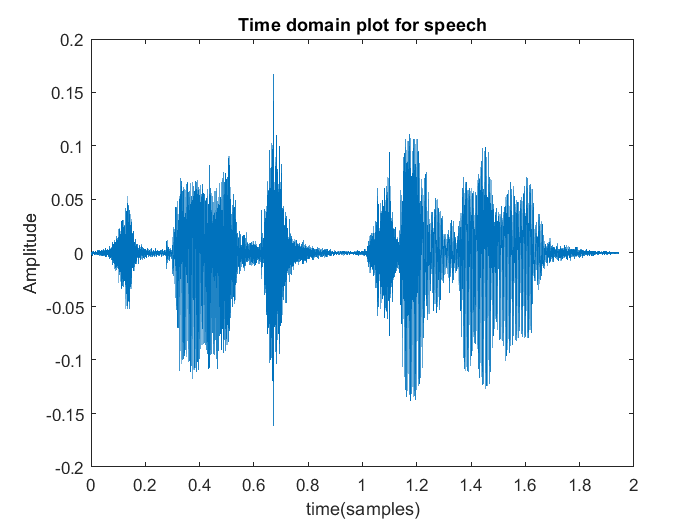

save speechsignal y fs;
y = y(:,1);
t1 = ((1:length(y))/fs);           % time duration
figure(1);
plot(t1,y);
xlabel('time(samples)');
ylabel('Amplitude');
title('Time domain plot for speech')

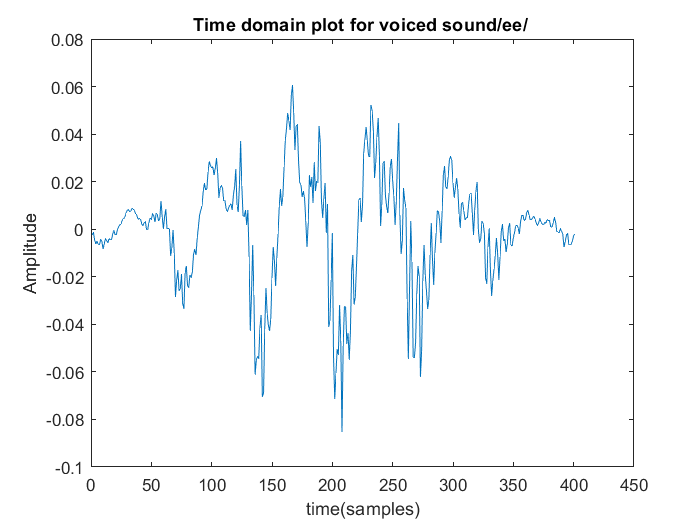


%voiced sound (ee)
y_voiced = y(ceil(0.400*fs):floor(0.425*fs));
N=length(y_voiced);
y_v = y_voiced.*hamming(length(y_voiced));%multiplying with hamming window
figure(2);
plot(y_v);
xlabel('time(samples)');
ylabel('Amplitude');
title('Time domain plot for voiced sound/ee/ ')

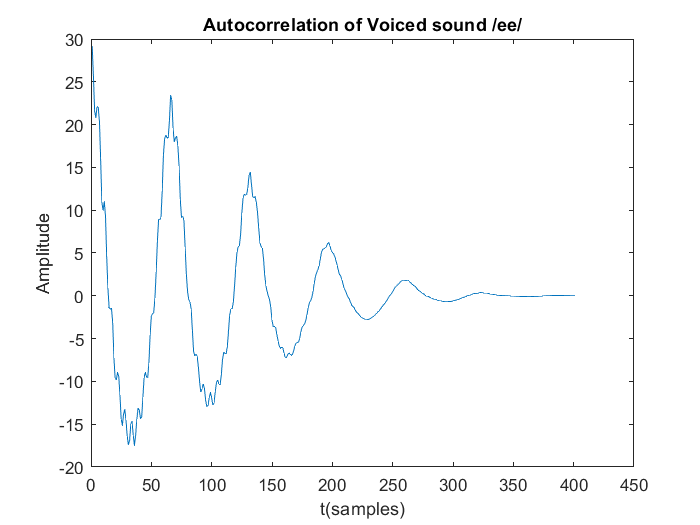


%autocorrelation
y_corr=autocorr(y_v,N);
figure(3);
plot(y_corr);
xlabel('t(samples)');
ylabel('Amplitude');
title('Autocorrelation of Voiced sound /ee/');

%taking matrix
P=10;
y_A=y_corr(1:P);%A
r=y_corr(2:P+1);%r
R=toeplitz(y_A);%toeplitz autocorrelation matrix
%%By direct matix soving method
L=-inv(R)*r';
L=L'

L =    -0.8114    0.2137   -0.0512   -0.7114    0.3844   -0.4759    0.0883    0.6540   -0.2588    0.0960


LP_coeff(1,1:length([1,L])) =[1,L]

LP_coeff =     1.0000   -0.8114    0.2137   -0.0512   -0.7114    0.3844   -0.4759    0.0883    0.6540   -0.2588    0.0960


B)Computing LP residual

- Using the computed LPCs, derive the LP residual signal.

%LP residuals:
LPres=conv(y_v,LP_coeff)%Inverse filtering;

LPres =    -0.0023
    0.0006
   -0.0040
   -0.0027
    0.0009
   -0.0036
    0.0020
    0.0028
   -0.0009
    0.0002


LPres=LPres(round(P/2):length(LPres)-round(P/2)-1);%removing additional samples caused due to convolution
figure(4);
plot(LPres);
xlabel('time(samples)');
ylabel('Amplitude');
title('LP Residual of Voiced speech segment /ee/');

C)Pitch estimation from LP residual:

- Estimate the pitch from the estimated LP residual using autocorrelation

%pitch estimation:
y_pitch=autocorr(LPres,N);
y_p=y_pitch(25:N)

y_p =    -0.3929    0.6751    0.4879   -1.0873   -0.6085    0.4402    0.4487   -2.4382   -0.9862    0.0417   -2.0908   -1.1958    1.1793   -0.6004   -0.0191   -0.5797    0.5788    0.5311    0.6728    1.3552    0.0989   -1.1247    0.0836    0.2981   -0.0175   -0.8856   -1.3678   -1.2273   -0.5091   -1.7487   -1.9551    0.7785   -0.9527   -0.8674   -0.2854    0.8502    0.7594    1.9804    1.1202    1.1396   -0.6188    4.4397    4.1637   -0.7095    0.5835    0.8280    1.0863    0.4097    0.3032   -0.3805


[M,mp]=max(y_p);   % finding the peak in autocorrelation of voiced sound
pitch_2ndmax = mp;
pitch_period=mp+25

pitch_period = 67

pitch_frequency=(1/pitch_period)*fs;

D)Formant estimation from LP spectrum:

- Explain, step by step, the procedure of computing the LP spectrum from LPCs.

- Demonstrate the same on the voiced frame selected above.

## **Theory:**

- The predicted sample s^(n) can be represented as follows

                                   

                     where *p* is the order of prediction, aks are the linear prediction coefficients and s(n) is the windowed speech sequence.

- The prediction error e(n) can be computed by the difference between actual sample s(n)and the predicted sample s^(n) which is given by,

                                  

- The primary objective of LP analysis is to compute the LP coefficients which minimized the prediction error e(n). 

- This can be achieved by computing the LP coefficients by least squares auto correlation method. It is done by minimizing the total prediction error. The total prediction error can be represented as follows,

                                 

              By simplifying this we get

                              

            where i=1, 2, 3...p

            The equation (9) can be written in terms of autocorrelation sequence R(i) as follows,

                              

           Where the autocorrelation sequence used in equation (10) can be written as follows, 

                             

           where N is length of sequence

           The LP coefficients can be computed as shown,

             where R is

                         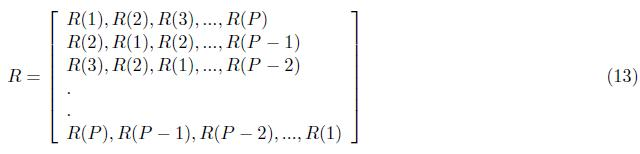

              Computing the LP residual by inverse filtering:

                    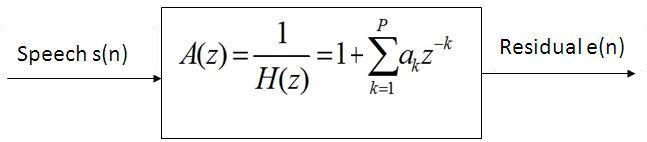

%formant estimation
Y_ee=abs(fft(LP_coeff,16000));
H_z=Y_ee.^-1;
H_z_dB=20*log(H_z);
figure(5);
%plot(H_z_dB(1:8000))%taking symmetric part of spectrum

% peak picking algorithm
% for voiced
k = 1;
for i=2:length(H_z_dB)-1
    if (H_z_dB(i-1)< H_z_dB(i)) & (H_z_dB(i+1)< H_z_dB(i))
        formant_mag(k) =H_z_dB(i);
        formant(k)=i;
        k = k+1;        
    end
end
formant

formant =          319        2973        4716        7427        8575       11286       13029       15683


figure(6);
f1 = (1:16000).*(fs/16000); 
plot(f1(1:8000),(H_z_dB(1:8000)));
hold on;
plot(formant(1:4),formant_mag(1:4),'r*');
hold off;
xlabel('frequency');
ylabel('Log magnitude spectrum');
title('Formant extracted from LP residuals')

E)Normalized Error

- Select the 25ms frame at the center of the voiced and unvoiced frame respectively. Compute the normalized LP residual error as a function of the order of LP prediction. Plot normalized error curve against the prediction order for both voiced and unvoiced frames

- Comment upon the choice of optimal prediction order for the  segments. 

%normalisation of error

y_voiced = y(ceil(0.400*fs):floor(0.425*fs));
N=length(y_voiced);
y_v = y_voiced.*hamming(length(y_voiced));%multiplying with hamming window
y_unvoiced = y(ceil(0.100*fs):floor(0.125*fs));
N1=length(y_unvoiced);
y_uv = y_unvoiced.*hamming(length(y_unvoiced));
%autocorrelation of voiced
y_corr=autocorr(y_v,N);
%autocorrelation of unvoiced
y_corr_uv=autocorr(y_uv,N1);
count_v=1;count_uv=1;
for P=(2:75)
%for voiced sound (ee)
%taking matrix
y_A=y_corr(1:P);%A
r=y_corr(2:P+1);%r
R=toeplitz(y_A);%toeplitz autocorrelation matrix
%%By direct matix soving method
L=-inv(R)*r';
L=L';
LP_coeff_v(1,1:length([1,L])) =[1,L];
%Normalised error:
Ep(count_v)=y_corr(1)+sum(LP_coeff_v(2:length(LP_coeff_v)).*y_corr(2:P+1));
count_v=count_v+1;%increment the counter
clearvars y_A r R L LP_coeff_v
%for unvoiced sound(s)
%taking matrix
y_A_uv=y_corr_uv(1:P);%A
r_uv=y_corr_uv(2:P+1);%r
R_uv=toeplitz(y_A_uv);%toeplitz autocorrelation matrix
%%By direct matix soving method
L1=-inv(R_uv)*r_uv';
L1=L1';
LP_coeff_uv(1,1:length([1,L1])) =[1,L1];
Ep1(count_uv)=y_corr_uv(1)+sum(LP_coeff_uv(2:length(LP_coeff_uv)).*y_corr_uv(2:P+1));
count_uv=count_uv+1;%increment the counter
clearvars y_A_uv r_uv R_uv L1 LP_coeff_uv
end

LP_coeff_v =     1.0000   -1.0212    0.1587


LP_coeff_v =     1.0000   -1.0915    0.6110   -0.4430


LP_coeff_v =     1.0000   -0.9818    0.4597   -0.1727   -0.2476


LP_coeff_v =     1.0000   -0.9943    0.4510   -0.1495   -0.2971    0.0504


LP_coeff_v =     1.0000   -0.9973    0.4686   -0.1407   -0.3237    0.1092   -0.0591


LP_coeff_v =     1.0000   -1.0360    0.5402   -0.3531   -0.4160    0.4165   -0.7133    0.6560


LP_coeff_v =     1.0000   -0.7005    0.1753   -0.1400   -0.6288    0.2360   -0.4370    0.1260    0.5115


LP_coeff_v =     1.0000   -0.7939    0.1523   -0.0602   -0.6719    0.3507   -0.4115    0.0940    0.6394   -0.1826


LP_coeff_v =     1.0000   -0.8114    0.2137   -0.0512   -0.7114    0.3844   -0.4759    0.0883    0.6540   -0.2588    0.0960


LP_coeff_v =     1.0000   -0.8332    0.2724   -0.1996   -0.7314    0.4924   -0.5632    0.2497    0.6656   -0.3072    0.2801   -0.2269


LP_coeff_v =     1.0000   -0.8075    0.2407   -0.1648   -0.8068    0.4641   -0.4994    0.1939    0.7485   -0.2846    0.2493   -0.1325   -0.1133


LP_coeff_v =     1.0000   -0.7880    0.2634   -0.2076   -0.7579    0.3356   -0.5327    0.2797    0.6688   -0.1461    0.2776   -0.1739    0.0254   -0.1718


LP_coeff_v =     1.0000   -0.8048    0.2659   -0.2246   -0.7307    0.3213   -0.4672    0.3071    0.6166   -0.1132    0.2033   -0.1942    0.0512   -0.2490    0.0980


LP_coeff_v =     1.0000   -0.8098    0.2785   -0.2272   -0.7209    0.3110   -0.4615    0.2759    0.6011   -0.0896    0.1871   -0.1573    0.0625   -0.2624    0.1386   -0.0505


LP_coeff_v =     1.0000   -0.8226    0.3136   -0.2937   -0.7051    0.2712   -0.4141    0.2533    0.7533   -0.0197    0.0702   -0.0785   -0.1200   -0.3199    0.2091   -0.2556    0.2533


LP_coeff_v =     1.0000   -0.8015    0.2924   -0.2763   -0.7317    0.2612   -0.4206    0.2591    0.7517    0.0429    0.0913   -0.1129   -0.0975   -0.3785    0.1847   -0.2295    0.1849    0.0831


LP_coeff_v =     1.0000   -0.8071    0.2799   -0.2609   -0.7441    0.2866   -0.4141    0.2667    0.7455    0.0400    0.0408   -0.1303   -0.0693   -0.3960    0.2338   -0.2110    0.1653    0.1369   -0.0671


LP_coeff_v =     1.0000   -0.8233    0.3129   -0.2211   -0.7948    0.3428   -0.5093    0.2500    0.7142    0.0498    0.0504    0.0490   -0.0051   -0.4956    0.3028   -0.3899    0.1025    0.2042   -0.2613    0.2405


LP_coeff_v =     1.0000   -0.7753    0.2608   -0.1804   -0.7744    0.2651   -0.4490    0.1512    0.7132    0.0596    0.0605    0.0589    0.1372   -0.4458    0.2013   -0.3216   -0.0559    0.1601   -0.1989    0.0764    0.1993


LP_coeff_v =     1.0000   -0.8014    0.2508   -0.1544   -0.7954    0.2724   -0.4068    0.1249    0.7716    0.0416    0.0527    0.0510    0.1294   -0.5392    0.1814   -0.2628   -0.0906    0.2616   -0.1752    0.0423    0.3009   -0.1310


LP_coeff_v =     1.0000   -0.8285    0.3130   -0.1456   -0.8316    0.3265   -0.4255    0.0705    0.8091   -0.0699    0.0795    0.0615    0.1403   -0.5306    0.3409   -0.2370   -0.1747    0.3179   -0.3396    0.0103    0.3527   -0.2967    0.2067


LP_coeff_v =     1.0000   -0.8128    0.2904   -0.1188   -0.8308    0.3007   -0.4013    0.0572    0.7911   -0.0439    0.0391    0.0722    0.1450   -0.5246    0.3356   -0.1754   -0.1693    0.2855   -0.3148   -0.0529    0.3417   -0.2729    0.1436    0.0761


LP_coeff_v =     1.0000   -0.8100    0.2956   -0.1288   -0.8183    0.2987   -0.4128    0.0677    0.7849   -0.0503    0.0514    0.0530    0.1503   -0.5220    0.3370   -0.1770   -0.1404    0.2876   -0.3295   -0.0419    0.3113   -0.2772    0.1542    0.0464    0.0365


LP_coeff_v =     1.0000   -0.8138    0.2908   -0.1449   -0.7893    0.2662   -0.4085    0.1022    0.7548   -0.0356    0.0699    0.0178    0.2049   -0.5377    0.3315   -0.1824   -0.1352    0.2055   -0.3365    0.0012    0.2801   -0.1916    0.1677    0.0155    0.1213   -0.1046


LP_coeff_v =     1.0000   -0.8172    0.2947   -0.1444   -0.7839    0.2600   -0.3994    0.1022    0.7439   -0.0290    0.0655    0.0119    0.2156   -0.5550    0.3381   -0.1818   -0.1329    0.2044   -0.3122    0.0045    0.2669   -0.1830    0.1423    0.0108    0.1307   -0.1308    0.0322


LP_coeff_v =     1.0000   -0.8199    0.3055   -0.1552   -0.7848    0.2483   -0.3844    0.0802    0.7436   -0.0033    0.0487    0.0228    0.2305   -0.5829    0.3838   -0.1996   -0.1339    0.1990   -0.3098   -0.0568    0.2585   -0.1501    0.1209    0.0754    0.1425   -0.1551    0.0995   -0.0824


LP_coeff_v =     1.0000   -0.8319    0.3201   -0.1779   -0.7639    0.2593   -0.3666    0.0582    0.7814   -0.0116    0.0033    0.0520    0.2109   -0.6121    0.4401   -0.2850   -0.1001    0.2023   -0.3027   -0.0572    0.3674   -0.1384    0.0646    0.1118    0.0275   -0.1779    0.1443   -0.2025    0.1465


LP_coeff_v =     1.0000   -0.8222    0.3065   -0.1683   -0.7758    0.2612   -0.3592    0.0625    0.7722    0.0129   -0.0005    0.0318    0.2244   -0.6188    0.4210   -0.2556   -0.1409    0.2164   -0.2992   -0.0570    0.3667   -0.0862    0.0684    0.0873    0.0448   -0.2288    0.1324   -0.1812    0.0910    0.0667


LP_coeff_v =     1.0000   -0.8221    0.3066   -0.1684   -0.7756    0.2609   -0.3591    0.0626    0.7723    0.0128   -0.0001    0.0317    0.2241   -0.6186    0.4209   -0.2559   -0.1405    0.2158   -0.2990   -0.0570    0.3667   -0.0862    0.0692    0.0874    0.0445   -0.2286    0.1316   -0.1813    0.0913    0.0659    0.0010


LP_coeff_v =     1.0000   -0.8220    0.3151   -0.1567   -0.7990    0.2779   -0.3886    0.0683    0.7835    0.0217   -0.0112    0.0790    0.2168   -0.6571    0.4487   -0.2740   -0.1735    0.2700   -0.3787   -0.0281    0.3708   -0.0862    0.0709    0.1868    0.0525   -0.2748    0.1652   -0.2812    0.0696    0.1054   -0.1049    0.1288


LP_coeff_v =     1.0000   -0.8149    0.3094   -0.1509   -0.7952    0.2625   -0.3795    0.0533    0.7864    0.0320   -0.0074    0.0742    0.2371   -0.6586    0.4280   -0.2592   -0.1830    0.2550   -0.3541   -0.0641    0.3826   -0.0819    0.0703    0.1880    0.0954   -0.2711    0.1440   -0.2660    0.0259    0.0968   -0.0876    0.0838    0.0547


LP_coeff_v =     1.0000   -0.8192    0.3029   -0.1441   -0.8027    0.2605   -0.3588    0.0421    0.8075    0.0245   -0.0220    0.0688    0.2435   -0.6884    0.4330   -0.2316   -0.2028    0.2692   -0.3339   -0.0974    0.4340   -0.1004    0.0645    0.1886    0.0929   -0.3324    0.1398   -0.2364    0.0054    0.1588   -0.0758    0.0597    0.1183   -0.0780


LP_coeff_v =     1.0000   -0.8394    0.3335   -0.1286   -0.8224    0.3016   -0.3574   -0.0192    0.8438   -0.0616    0.0021    0.1176    0.2602   -0.7145    0.5454   -0.2568   -0.2894    0.3390   -0.3865   -0.1575    0.5462   -0.2788    0.1276    0.2064    0.0872   -0.3260    0.3491   -0.2255   -0.0875    0.2263   -0.2839    0.0223    0.1968   -0.2903    0.2592


LP_coeff_v =     1.0000   -0.8152    0.3064   -0.1102   -0.8203    0.2751   -0.3362   -0.0274    0.8227   -0.0290   -0.0284    0.1258    0.2795   -0.7025    0.5194   -0.2058   -0.3041    0.3029   -0.3548   -0.1845    0.5222   -0.2279    0.0608    0.2307    0.0982   -0.3258    0.3434   -0.1467   -0.0893    0.1929   -0.2557   -0.0545    0.1847   -0.2591    0.1808    0.0934


LP_coeff_v =     1.0000   -0.8037    0.3287   -0.1422   -0.7975    0.2684   -0.3678   -0.0036    0.8117   -0.0471    0.0139    0.0856    0.2916   -0.6741    0.5269   -0.2339   -0.2397    0.2802   -0.3985   -0.1472    0.4847   -0.2532    0.1248    0.1441    0.1327   -0.3103    0.3399   -0.1503    0.0120    0.1896   -0.2972   -0.0206    0.0837   -0.2727    0.2185   -0.0070    0.1232


LP_coeff_v =     1.0000   -0.8029    0.3286   -0.1408   -0.7993    0.2689   -0.3679   -0.0055    0.8129   -0.0470    0.0129    0.0878    0.2896   -0.6732    0.5278   -0.2331   -0.2414    0.2833   -0.3995   -0.1498    0.4865   -0.2548    0.1233    0.1475    0.1283   -0.3085    0.3404   -0.1502    0.0117    0.1948   -0.2972   -0.0230    0.0854   -0.2779    0.2176   -0.0049    0.1180    0.0065


LP_coeff_v =     1.0000   -0.8026    0.3332   -0.1409   -0.7909    0.2582   -0.3646   -0.0064    0.8015   -0.0395    0.0134    0.0820    0.3027   -0.6851    0.5328   -0.2274   -0.2366    0.2735   -0.3807   -0.1555    0.4711   -0.2439    0.1140    0.1386    0.1487   -0.3344    0.3516   -0.1468    0.0122    0.1930   -0.2658   -0.0232    0.0712   -0.2675    0.1868   -0.0103    0.1307   -0.0245    0.0386


LP_coeff_v =     1.0000   -0.7966    0.3294   -0.1207   -0.7925    0.2872   -0.4061    0.0046    0.7979   -0.0807    0.0433    0.0839    0.2799   -0.6306    0.4809   -0.2043   -0.2151    0.2912   -0.4185   -0.0825    0.4470   -0.3029    0.1564    0.1018    0.1134   -0.2518    0.2453   -0.0999    0.0250    0.1951   -0.2720    0.1011    0.0702   -0.3241    0.2268   -0.1330    0.1088    0.0272   -0.0859    0.1551


LP_coeff_v =     1.0000   -0.7774    0.3187   -0.1173   -0.7790    0.2707   -0.3779   -0.0356    0.8066   -0.0682    0.0096    0.1082    0.2830   -0.6430    0.5113   -0.2356   -0.2011    0.3038   -0.3991   -0.1201    0.5025   -0.3131    0.1045    0.1380    0.0867   -0.2772    0.3050   -0.1782    0.0597    0.2055   -0.2666    0.0911    0.1693   -0.3235    0.1764   -0.0974    0.0104    0.0122   -0.0450    0.0562    0.1242


LP_coeff_v =     1.0000   -0.7615    0.3259   -0.1231   -0.7774    0.2720   -0.3904   -0.0131    0.7652   -0.0465    0.0212    0.0740    0.3093   -0.6354    0.4885   -0.1966   -0.2365    0.3149   -0.3814   -0.1067    0.4624   -0.2488    0.0891    0.0869    0.1256   -0.3029    0.2749   -0.1127   -0.0226    0.2417   -0.2527    0.0923    0.1606   -0.2203    0.1718   -0.1457    0.0451   -0.0875   -0.0600    0.0970    0.0247    0.1280


LP_coeff_v =     1.0000   -0.7336    0.3313   -0.1020   -0.7905    0.2530   -0.3806   -0.0447    0.8025   -0.0944    0.0561    0.0941    0.2544   -0.5828    0.4836   -0.2211   -0.1768    0.2490   -0.3541   -0.0878    0.4818   -0.3029    0.1896    0.0637    0.0426   -0.2344    0.2234   -0.1555    0.0837    0.1036   -0.1855    0.1084    0.1652   -0.2304    0.3382   -0.1486   -0.0398   -0.0284   -0.2291    0.0702    0.0956   -0.0376    0.2174


LP_coeff_v =     1.0000   -0.7169    0.3284   -0.0946   -0.7851    0.2354   -0.3828   -0.0478    0.7911   -0.0684    0.0384    0.1068    0.2627   -0.5970    0.4916   -0.2146   -0.1887    0.2662   -0.3721   -0.0845    0.4867   -0.2884    0.1664    0.1007    0.0359   -0.2616    0.2426   -0.1690    0.0667    0.1407   -0.2302    0.1280    0.1724   -0.2261    0.3310   -0.0869   -0.0433   -0.0576   -0.2097    0.0095    0.0877   -0.0121    0.1611    0.0768


LP_coeff_v =     1.0000   -0.7240    0.3135   -0.0935   -0.7932    0.2345   -0.3634   -0.0425    0.7951   -0.0604    0.0080    0.1276    0.2468   -0.6088    0.5128   -0.2276   -0.1948    0.2818   -0.3945   -0.0604    0.4834   -0.2977    0.1511    0.1273   -0.0090   -0.2538    0.2768   -0.1936    0.0841    0.1605   -0.2755    0.1830    0.1482   -0.2359    0.3274   -0.0806   -0.1161   -0.0532   -0.1744   -0.0122    0.1600   -0.0034    0.1309    0.1428   -0.0921


LP_coeff_v =     1.0000   -0.7231    0.3121   -0.0949   -0.7931    0.2329   -0.3633   -0.0407    0.7957   -0.0592    0.0088    0.1243    0.2492   -0.6104    0.5109   -0.2248   -0.1965    0.2809   -0.3925   -0.0633    0.4860   -0.2976    0.1497    0.1257   -0.0059   -0.2588    0.2775   -0.1895    0.0812    0.1625   -0.2732    0.1777    0.1545   -0.2384    0.3261   -0.0807   -0.1155   -0.0614   -0.1740   -0.0084    0.1576    0.0047    0.1318    0.1396   -0.0847   -0.0103


LP_coeff_v =     1.0000   -0.7238    0.3058   -0.0845   -0.7834    0.2332   -0.3517   -0.0413    0.7828   -0.0638    0.0003    0.1183    0.2733   -0.6280    0.5223   -0.2117   -0.2167    0.2929   -0.3865   -0.0773    0.5065   -0.3167    0.1493    0.1350    0.0052   -0.2808    0.3134   -0.1942    0.0522    0.1832   -0.2877    0.1611    0.1922   -0.2835    0.3445   -0.0715   -0.1149   -0.0657   -0.1152   -0.0114    0.1308    0.0219    0.0732    0.1326   -0.0616   -0.0637    0.0739


LP_coeff_v =     1.0000   -0.7227    0.3048   -0.0855   -0.7814    0.2343   -0.3513   -0.0393    0.7826   -0.0655   -0.0007    0.1166    0.2722   -0.6228    0.5180   -0.2087   -0.2142    0.2886   -0.3837   -0.0765    0.5036   -0.3119    0.1451    0.1351    0.0072   -0.2785    0.3086   -0.1865    0.0510    0.1774


LP_coeff_v =     1.0000   -0.7231    0.3031   -0.0838   -0.7796    0.2309   -0.3535   -0.0398    0.7790   -0.0655    0.0025    0.1184    0.2754   -0.6209    0.5086   -0.2010   -0.2195    0.2841   -0.3758   -0.0815    0.5021   -0.3067    0.1364    0.1429    0.0070   -0.2823    0.3045   -0.1778    0.0369    0.1795


LP_coeff_v =     1.0000   -0.7225    0.3023   -0.0850   -0.7784    0.2318   -0.3560   -0.0417    0.7786   -0.0679    0.0025    0.1210    0.2769   -0.6182    0.5098   -0.2082   -0.2135    0.2798   -0.3791   -0.0754    0.4981   -0.3075    0.1404    0.1361    0.0133   -0.2825    0.3013   -0.1808    0.0437    0.1683


LP_coeff_v =     1.0000   -0.7183    0.3045   -0.0904   -0.7890    0.2392   -0.3473   -0.0647    0.7621   -0.0680   -0.0182    0.1206    0.2993   -0.6040    0.5299   -0.1966   -0.2748    0.3297   -0.4147   -0.1052    0.5491   -0.3393    0.1321    0.1702   -0.0435   -0.2292    0.2988   -0.2065    0.0173    0.2263


LP_coeff_v =     1.0000   -0.7088    0.2988   -0.0869   -0.7912    0.2290   -0.3431   -0.0658    0.7555   -0.0650   -0.0189    0.1150    0.3004   -0.5954    0.5278   -0.1863   -0.2737    0.3112   -0.3986   -0.1184    0.5404   -0.3208    0.1207    0.1693   -0.0330   -0.2444    0.3104   -0.2043    0.0086    0.2196


LP_coeff_v =     1.0000   -0.7108    0.2926   -0.0829   -0.7939    0.2324   -0.3353   -0.0685    0.7565   -0.0613   -0.0212    0.1156    0.3046   -0.5968    0.5221   -0.1857   -0.2815    0.3109   -0.3843   -0.1305    0.5513   -0.3149    0.1065    0.1783   -0.0327   -0.2527    0.3231   -0.2142    0.0073    0.2265


LP_coeff_v =     1.0000   -0.7063    0.2837   -0.0984   -0.7834    0.2217   -0.3249   -0.0489    0.7490   -0.0552   -0.0113    0.1093    0.3067   -0.5840    0.5154   -0.1989   -0.2808    0.2883   -0.3838   -0.0937    0.5179   -0.2830    0.1210    0.1404   -0.0076   -0.2519    0.2994   -0.1784   -0.0207    0.2229


LP_coeff_v =     1.0000   -0.7066    0.2838   -0.0983   -0.7830    0.2217   -0.3247   -0.0490    0.7485   -0.0552   -0.0115    0.1091    0.3068   -0.5842    0.5153   -0.1989   -0.2804    0.2883   -0.3834   -0.0936    0.5170   -0.2824    0.1204    0.1400   -0.0068   -0.2525    0.2994   -0.1780   -0.0215    0.2236


LP_coeff_v =     1.0000   -0.7063    0.2698   -0.0935   -0.7771    0.2400   -0.3255   -0.0403    0.7414   -0.0760   -0.0134    0.1031    0.2961   -0.5786    0.5086   -0.2049   -0.2802    0.3056   -0.3803   -0.0726    0.5218   -0.3218    0.1502    0.1086   -0.0246   -0.2123    0.2716   -0.1753    0.0007    0.1863


LP_coeff_v =     1.0000   -0.7263    0.2835   -0.0810   -0.7814    0.2481   -0.3536   -0.0328    0.7311   -0.0819    0.0146    0.1059    0.3017   -0.5709    0.5131   -0.2065   -0.2685    0.3109   -0.4084   -0.0689    0.4965   -0.3383    0.2068    0.0676    0.0132   -0.1892    0.2248   -0.1453    0.0008    0.1581


LP_coeff_v =     1.0000   -0.7475    0.3149   -0.0980   -0.7896    0.2681   -0.3654   -0.0029    0.7258   -0.0892    0.0210    0.0832    0.2972   -0.5818    0.5191   -0.2210   -0.2628    0.3073   -0.4192   -0.0379    0.4950   -0.3286    0.2271    0.0181    0.0445   -0.2196    0.2103   -0.1127   -0.0200    0.1579


LP_coeff_v =     1.0000   -0.7494    0.3186   -0.1019   -0.7876    0.2704   -0.3680   -0.0009    0.7227   -0.0900    0.0219    0.0825    0.2994   -0.5819    0.5213   -0.2226   -0.2609    0.3072   -0.4194   -0.0359    0.4918   -0.3294    0.2267    0.0155    0.0497   -0.2230    0.2140   -0.1116   -0.0233    0.1602


LP_coeff_v =     1.0000   -0.7486    0.3111   -0.0882   -0.8022    0.2772   -0.3591   -0.0109    0.7298   -0.1012    0.0189    0.0860    0.2969   -0.5733    0.5206   -0.2139   -0.2670    0.3142   -0.4196   -0.0369    0.4990   -0.3410    0.2235    0.0142    0.0401   -0.2036    0.2012   -0.0980   -0.0191    0.1481


LP_coeff_v =     1.0000   -0.7485    0.3110   -0.0884   -0.8018    0.2767   -0.3589   -0.0107    0.7295   -0.1009    0.0186    0.0859    0.2970   -0.5734    0.5208   -0.2139   -0.2668    0.3140   -0.4193   -0.0370    0.4989   -0.3407    0.2232    0.0141    0.0401   -0.2039    0.2018   -0.0983   -0.0187    0.1483


LP_coeff_v =     1.0000   -0.7484    0.3143   -0.0900   -0.8099    0.2931   -0.3794   -0.0015    0.7392   -0.1130    0.0298    0.0719    0.2933   -0.5688    0.5185   -0.2053   -0.2659    0.3239   -0.4277   -0.0273    0.4973   -0.3420    0.2336   -0.0012    0.0371   -0.2055    0.1902   -0.0753   -0.0337    0.1646


LP_coeff_v =     1.0000   -0.7384    0.3071   -0.0789   -0.8146    0.2656   -0.3372   -0.0544    0.7611   -0.0826   -0.0004    0.0990    0.2606   -0.5744    0.5238   -0.2054   -0.2475    0.3232   -0.4009   -0.0516    0.5200   -0.3410    0.2270    0.0260    0.0006   -0.2124    0.1844   -0.1009    0.0205    0.1287


LP_coeff_v =     1.0000   -0.7362    0.3063   -0.0788   -0.8138    0.2634   -0.3392   -0.0512    0.7561   -0.0788    0.0022    0.0962    0.2633   -0.5769    0.5220   -0.2037   -0.2480    0.3244   -0.4002   -0.0500    0.5176   -0.3377    0.2263    0.0259    0.0031   -0.2157    0.1833   -0.1011    0.0179    0.1337


LP_coeff_v =     1.0000   -0.7358    0.3096   -0.0799   -0.8138    0.2644   -0.3426   -0.0544    0.7609   -0.0864    0.0081    0.1003    0.2590   -0.5725    0.5180   -0.2064   -0.2455    0.3235   -0.3983   -0.0491    0.5200   -0.3412    0.2313    0.0249    0.0030   -0.2117    0.1780   -0.1027    0.0177    0.1297


LP_coeff_v =     1.0000   -0.7357    0.3096   -0.0789   -0.8141    0.2643   -0.3423   -0.0554    0.7600   -0.0848    0.0058    0.1020    0.2602   -0.5738    0.5192   -0.2075   -0.2463    0.3242   -0.3985   -0.0486    0.5203   -0.3404    0.2302    0.0264    0.0027   -0.2118    0.1791   -0.1043    0.0172    0.1296


LP_coeff_v =     1.0000   -0.7347    0.3122   -0.0789   -0.7927    0.2566   -0.3446   -0.0484    0.7373   -0.1037    0.0384    0.0549    0.2965   -0.5478    0.4927   -0.1819   -0.2696    0.3067   -0.3832   -0.0530    0.5306   -0.3344    0.2467    0.0038    0.0345   -0.2178    0.1781   -0.0799   -0.0154    0.1188


LP_coeff_v =     1.0000   -0.7193    0.3015   -0.0722   -0.7940    0.2604   -0.3464   -0.0554    0.7418   -0.1094    0.0226    0.0799    0.2619   -0.5160    0.5038   -0.1942   -0.2532    0.2851   -0.3916   -0.0475    0.5265   -0.3185    0.2460    0.0200    0.0176   -0.1934    0.1702   -0.0780    0.0016    0.0941


LP_coeff_v =     1.0000   -0.7157    0.3036   -0.0743   -0.7922    0.2572   -0.3443   -0.0572    0.7395   -0.1054    0.0205    0.0753    0.2697   -0.5254    0.5114   -0.1891   -0.2576    0.2891   -0.3971   -0.0514    0.5280   -0.3178    0.2496    0.0206    0.0225   -0.1984    0.1768   -0.0797    0.0019    0.0992


LP_coeff_v =     1.0000   -0.7151    0.3051   -0.0730   -0.7934    0.2577   -0.3459   -0.0563    0.7385   -0.1062    0.0226    0.0741    0.2672   -0.5210    0.5061   -0.1847   -0.2549    0.2866   -0.3948   -0.0545    0.5258   -0.3167    0.2498    0.0227    0.0229   -0.1957    0.1740   -0.0760    0.0009    0.0994


LP_coeff_v =     1.0000   -0.7130    0.3076   -0.0619   -0.7848    0.2479   -0.3420   -0.0679    0.7447   -0.1114    0.0168    0.0886    0.2597   -0.5374    0.5349   -0.2205   -0.2249    0.3042   -0.4114   -0.0394    0.5039   -0.3303    0.2568    0.0244    0.0374   -0.1930    0.1918   -0.0950    0.0260    0.0926


LP_coeff_v =     1.0000   -0.7034    0.3021   -0.0575   -0.7784    0.2458   -0.3458   -0.0687    0.7367   -0.1004    0.0125    0.0852    0.2697   -0.5396    0.5194   -0.1973   -0.2495    0.3210   -0.3973   -0.0538    0.5130   -0.3393    0.2451    0.0312    0.0387   -0.1835    0.1917   -0.0819    0.0132    0.1086


LP_coeff_v =     1.0000   -0.7045    0.3012   -0.0568   -0.7791    0.2455   -0.3457   -0.0677    0.7369   -0.0998    0.0106    0.0859    0.2702   -0.5417    0.5204   -0.1951   -0.2534    0.3256   -0.4007   -0.0559    0.5156   -0.3415    0.2470    0.0331    0.0374   -0.1838    0.1902   -0.0821    0.0109    0.1109


LP_coeff_v =     1.0000   -0.7035    0.2948   -0.0614   -0.7758    0.2409   -0.3469   -0.0675    0.7424   -0.0979    0.0137    0.0763    0.2743   -0.5387    0.5091   -0.1894   -0.2423    0.3050   -0.3760   -0.0737    0.5049   -0.3273    0.2353    0.0436    0.0469   -0.1903    0.1886   -0.0897    0.0099    0.0993


LP_coeff_v =     1.0000   -0.7051    0.2956   -0.0599   -0.7744    0.2412   -0.3460   -0.0666    0.7424   -0.1007    0.0133    0.0754    0.2770   -0.5403    0.5090   -0.1869   -0.2437    0.3021   -0.3704   -0.0803    0.5102   -0.3249    0.2316    0.0467    0.0437   -0.1932    0.1908   -0.0895    0.0123    0.0996


LP_coeff_v =     1.0000   -0.7045    0.2933   -0.0588   -0.7727    0.2425   -0.3455   -0.0656    0.7435   -0.1002    0.0099    0.0749    0.2759   -0.5369    0.5068   -0.1866   -0.2408    0.3003   -0.3737   -0.0738    0.5022   -0.3182    0.2343    0.0424    0.0475   -0.1970    0.1873   -0.0867    0.0124    0.1024


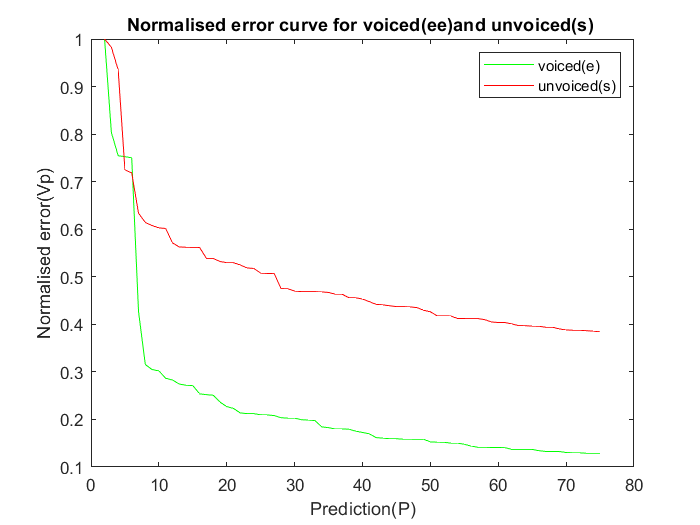

figure(7);
plot([2:75],Ep/max(Ep),'g');
hold on;
plot([2:75],Ep1/max(Ep1),'r');
hold off;

xlabel('Prediction(P)');
ylabel('Normalised error(Vp)');
legend('voiced(e)','unvoiced(s)');
title('Normalised error curve for voiced(ee)and unvoiced(s) ')

## `Observations:`

we observed from the graph that there is no significant reduction in the normalized error after a particular P. Therefore, this normalized error curve helps us to choose the optimum prediction order for the LP analysis.


%function of autocorrelation function

function [a]=autocorr(y,N)

window_length=N;
max_value=max(abs(y));
y=y/max_value;
y=y(1:window_length);
sum=0;
autocorrelation=[];
for l=0: (length(y)-1)
    sum=0;
    for u=1:length(y)-l
        s=y(u)*y(u+l);
        sum=sum+s;
    end
    autocorrelation(l+1)=sum;
end
a=autocorrelation;
end